# Matrices de Rotacion Basicas

A continuacion encuentra un ejemplo que ilustra la aplicacion de las matrices de rotacion basicas sobre sistemas de referencia en 3D.

Se inicia con un valor de angulo en radianes (-pi,pi). Los ejes iniciales antes de rotar se repesentan por vectores columna dentro de una matriz

ang = 1.4584;
axes_o = [1 0 0;0 1 0;0 0 1]; %ejes iniciales

## Rotacion sobre eje X

%Aplicando la rotacion en torno al eje X
R_x = [1 0 0; ...
    0 cos(ang) -sin(ang); ...
    0 sin(ang) cos(ang)]

R_x =     1.0000         0         0
         0    0.1122   -0.9937
         0    0.9937    0.1122


axes_fx = R_x * axes_o

axes_fx =     1.0000         0         0
         0    0.1122   -0.9937
         0    0.9937    0.1122


%grafica
figure()
hold on

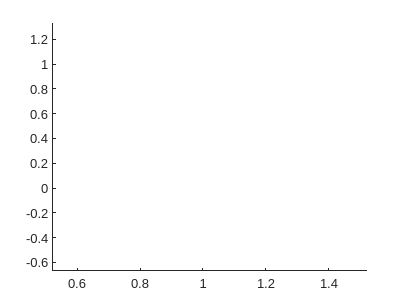


plot3(0:axes_fx(1,1),0:axes_fx(2,1),0:axes_fx(3,1),'--r');
plot3(0:axes_fx(1,2),0:axes_fx(2,2),0:axes_fx(3,2),'--g');

hold off